 Loading the battery dataset

%% STEP 1: Download and Load Battery Dataset
dataFile = matlab.internal.examples.downloadSupportFile("predmaint","batteryagingdata/singlecell/v1/singleCellLifeTimeData.zip");
unzip(dataFile);
load("singleCellLifeTimeData.mat");

%% STEP 2: Parse and Segment Data
bParser = batteryTestDataParser(data);
bParser.CurrentVariable = 'Current';
bParser.VoltageVariable = 'Voltage';
bParser.TimeVariable = 'DateTime';
bParser.CycleIndexVariable = 'Cycle_Index';
bParser.StepIndexVariable = 'Step_Index';  
segmentedRawDataTable = segmentData(bParser);

%% STEP 3: Extract All Valid "Charge" Data for Cycle 1
chargingData = segmentedRawDataTable(...
    segmentedRawDataTable.Cycle_Index == 1 & ...
    segmentedRawDataTable.CyclingPhases == "Charge", :);
chargingData.TimeInSeconds = seconds(chargingData.DateTime - chargingData.DateTime(1));


Fitting the CC_CV phase:

% Identify CC-CV Transition point (where Voltage reaches ~99.5% of peak)
vCutoff = 0.995 * max(chargingData.Voltage);
transitionIdx = find(chargingData.Voltage >= vCutoff, 1, 'first');

% Split into separate tables
ccData = chargingData(1:transitionIdx, :);
cvData = chargingData(transitionIdx:end, :);

%% STEP 2: Analyze & Fit CC Phase (Voltage vs. Time)
% Reset CC time so it starts at t_cc = 0
t_cc = ccData.TimeInSeconds - ccData.TimeInSeconds(1);
v_cc = ccData.Voltage;

Vmax_cc = max(v_cc);

% Define CC Model: V(t) = Vmax * (1 - exp(-t / tau_cc))
ft_cc = fittype(sprintf('%f * (1 - exp(-t / tau_cc))', Vmax_cc), ...
    'independent', 't', 'coefficients', 'tau_cc');

% Initial guess using 63.2% rule
[~, idx_guess] = min(abs(v_cc - 0.632 * Vmax_cc));
opts_cc = fitoptions(ft_cc);
opts_cc.StartPoint = t_cc(idx_guess);
opts_cc.Lower = 0.001;

[fitResult_cc, gof_cc] = fit(t_cc, v_cc, ft_cc, opts_cc);
tau_cc = fitResult_cc.tau_cc;

%% STEP 3: Analyze & Fit CV Phase (Current Decay vs. Time)
% Reset CV time so it starts at t_cv = 0
t_cv = cvData.TimeInSeconds - cvData.TimeInSeconds(1);
i_cv = cvData.Current;

% Define CV Model: I(t) = I0 * exp(-t / tau_cv)
ft_cv = fittype('I0 * exp(-t / tau_cv)', ...
    'independent', 't', 'coefficients', {'I0', 'tau_cv'});

opts_cv = fitoptions(ft_cv);
opts_cv.StartPoint = [i_cv(1), max(t_cv)/3]; % Initial guess [I0, tau_cv]
opts_cv.Lower = [0, 0.001];

[fitResult_cv, gof_cv] = fit(t_cv, i_cv, ft_cv, opts_cv);
I0_cv = fitResult_cv.I0;
tau_cv = fitResult_cv.tau_cv;

%% STEP 4: Display Fitted Parameters & Statistics
fprintf('====================================================\n');

fprintf('                CC PHASE RESULTS (Voltage)          \n');

                CC PHASE RESULTS (Voltage)          


fprintf('====================================================\n');

fprintf('Fitted Tau (tau_cc) : %.4f seconds\n', tau_cc);

Fitted Tau (tau_cc) : 0.2240 seconds


fprintf('R-squared           : %.4f\n', gof_cc.rsquare);

R-squared           : 0.1245


fprintf('Root Mean Square Error                : %.4f V\n\n', gof_cc.rmse);

Root Mean Square Error                : 0.3139 V




fprintf('====================================================\n');

fprintf('                CV PHASE RESULTS (Current Decay)    \n');

                CV PHASE RESULTS (Current Decay)    


fprintf('====================================================\n');

fprintf('Fitted Initial I0   : %.4f A\n', I0_cv);

Fitted Initial I0   : 0.8192 A


fprintf('Fitted Tau (tau_cv) : %.4f seconds\n', tau_cv);

Fitted Tau (tau_cv) : 144.1529 seconds


fprintf('R-squared           : %.4f\n', gof_cv.rsquare);

R-squared           : 0.8919


fprintf('Root Mean Square Error                : %.4f A\n', gof_cv.rmse);

Root Mean Square Error                : 0.0674 A


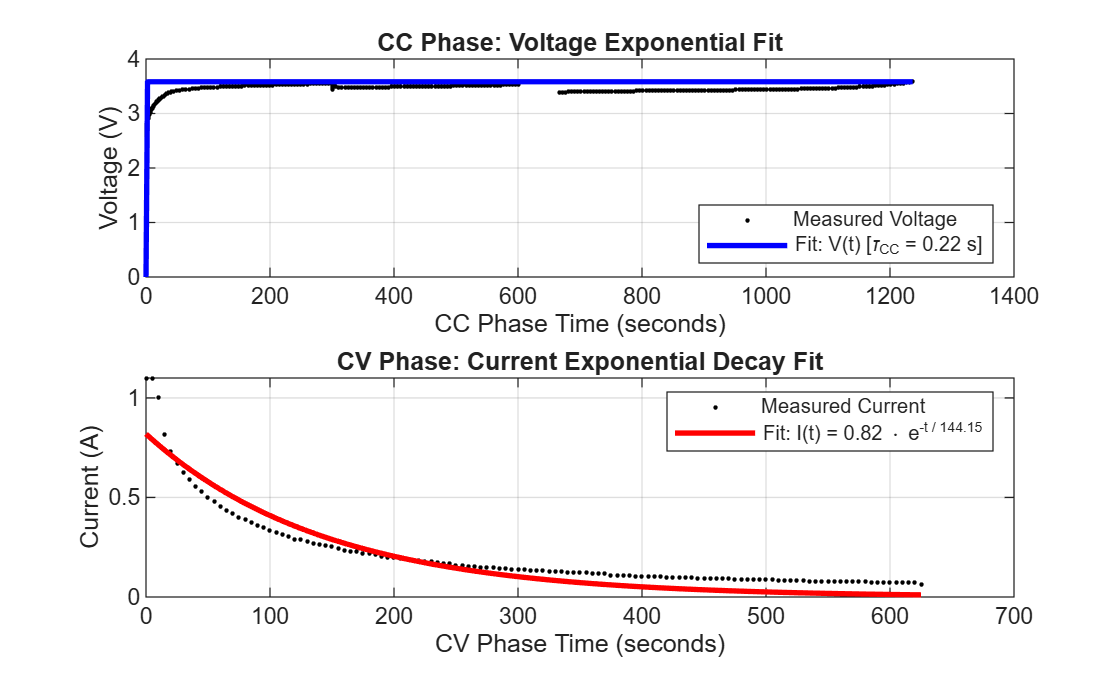


%% STEP 5: Plot Results
figure('Name', 'Separate CC and CV Phase Exponential Fits');

% --- Subplot 1: CC Phase (Voltage Fit) ---
subplot(2, 1, 1);
tSmooth_cc = linspace(0, max(t_cc), 500)';
vFitted = Vmax_cc * (1 - exp(-tSmooth_cc / tau_cc));

plot(t_cc, v_cc, '.k', 'MarkerSize', 5, 'DisplayName', 'Measured Voltage');
hold on;
plot(tSmooth_cc, vFitted, '-b', 'LineWidth', 2, ...
    'DisplayName', sprintf('Fit: V(t) [\\tau_{CC} = %.2f s]', tau_cc));
hold off;

xlabel('CC Phase Time (seconds)');
ylabel('Voltage (V)');
title('CC Phase: Voltage Exponential Fit');
legend('Location', 'southeast');
grid on;

% --- Subplot 2: CV Phase (Current Decay Fit) ---
subplot(2, 1, 2);
tSmooth_cv = linspace(0, max(t_cv), 500)';
iFitted = I0_cv * exp(-tSmooth_cv / tau_cv);

plot(t_cv, i_cv, '.k', 'MarkerSize', 5, 'DisplayName', 'Measured Current');
hold on;
plot(tSmooth_cv, iFitted, '-r', 'LineWidth', 2, ...
    'DisplayName', sprintf('Fit: I(t) = %.2f \\cdot e^{-t / %.2f}', I0_cv, tau_cv));
hold off;

xlabel('CV Phase Time (seconds)');
ylabel('Current (A)');
title('CV Phase: Current Exponential Decay Fit');
legend('Location', 'northeast');
grid on;